clearvars;

roots([1 -8 15])

ans =      5
     3


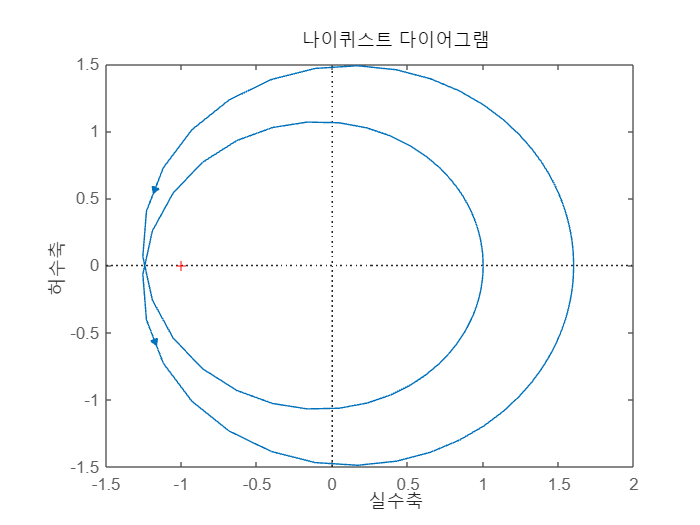

s = tf('s');
G = (s^2 + 10*s +24)/(s^2 - 8*s +15);
nyquist(G)

isstable(feedback(G,1))

ans = logical
   1

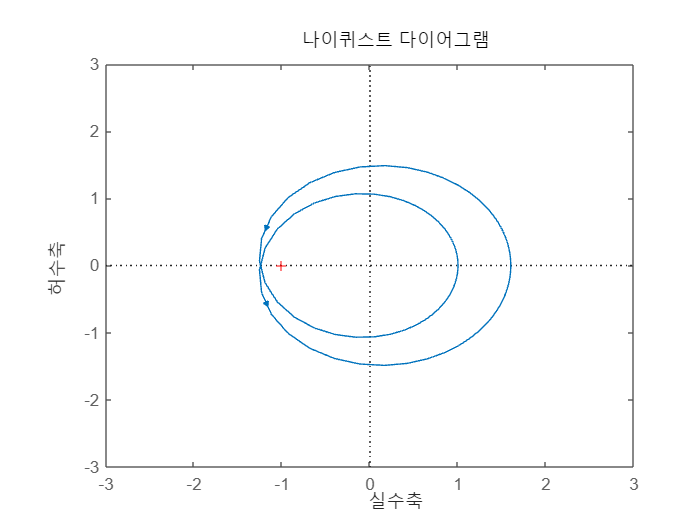

G = (s^2 + 10*s +24)/(s^2 - 8*s +15);
K = 1;
f1 = figure;
nyquist(K*G);
axis([-3 3 -3 3])

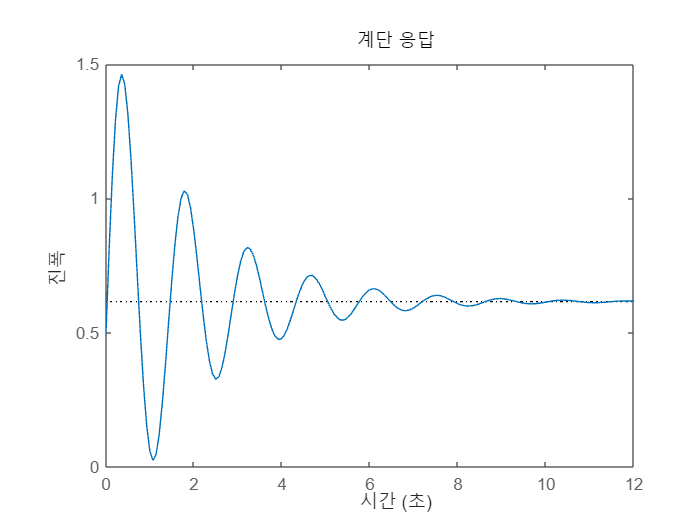

clf(f1)
f2 = figure;
step(feedback(K*G,1));

isstable(feedback(K*G,1))

ans = logical
   1

clf(f2)

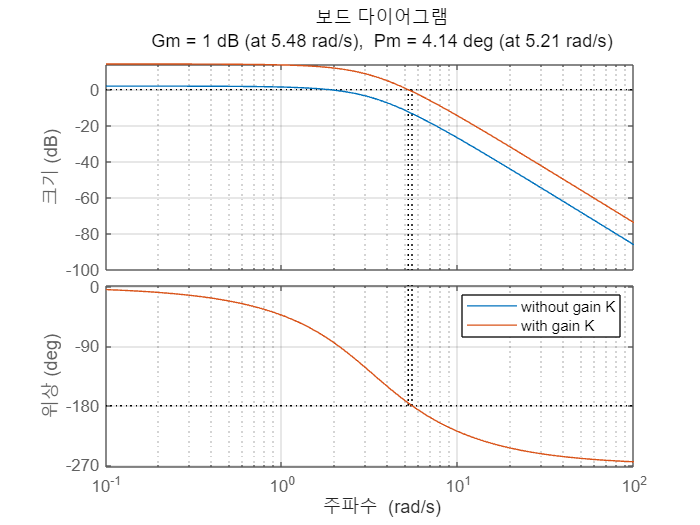

s = tf('s');
G = 50/(s^3 + 9*s^2 + 30*s + 40);
f1 = figure;
bode(G);
grid on
hold on
K = 4.1;
margin(K*G);
legend('without gain K','with gain K')
hold off

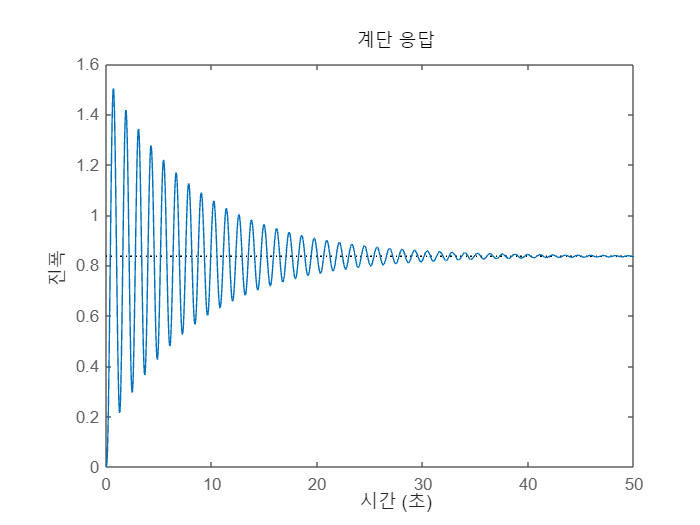

clf(f1)
f2 = figure;
step(feedback(K*G,1));

clf(f2)
isstable(feedback(K*G,1))

ans = logical
   1